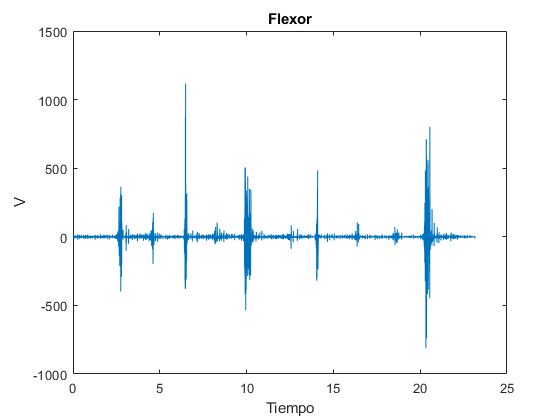

%EVALUACION INICIAL DEL ESPECTRO DE FRECUENCIAS
%Definicion de la señal inicial
clc
clear all
close all
%Cargamos el arhcivo
load('EMG 2 channel Wrist Flex_Ext_Raw.mat')
time=Data{1};
flex=Data{2};
exte=Data{3};

%Visualizaciona de datos sin procesar


plot(time, flex)
xlabel("Tiempo")
ylabel("V")
title("Flexor")

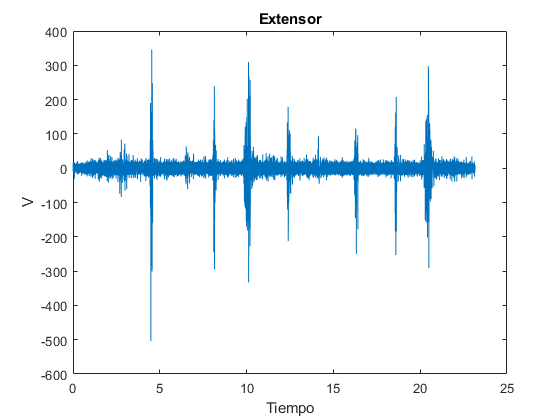


plot(time, exte)
xlabel("Tiempo")
ylabel("V")
title("Extensor")

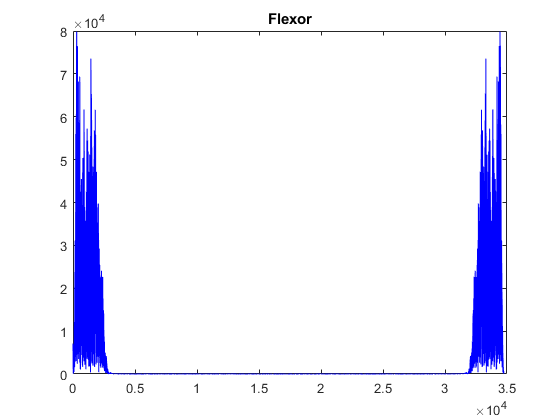


Frflex=fft(flex);%Aplicamos transformada rapida de fourier
Frexte=fft(exte);

plot(abs(Frflex),'b')
title("Flexor")

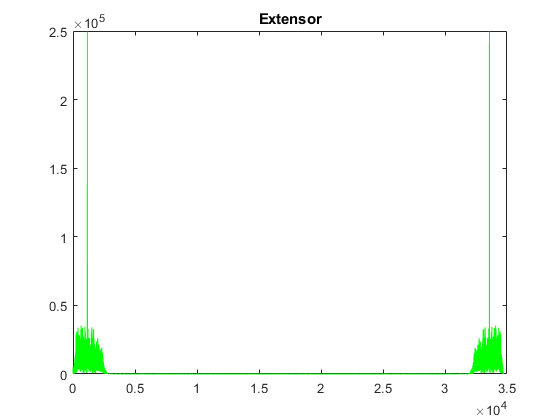


plot(abs(Frexte),'g')
title("Extensor")

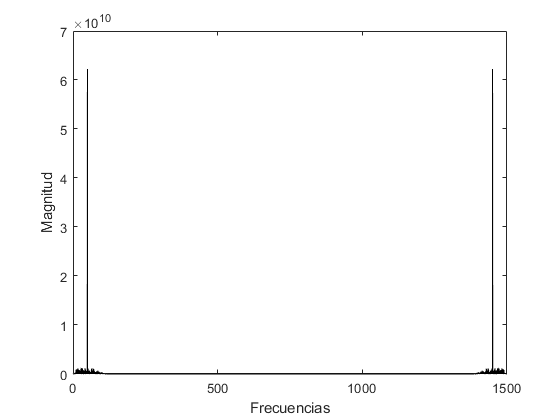



fs=1500;

n1=size(Frflex,1);
vectFreq=(0:n1-1)*(fs/n1);
power=abs(Frexte.^2);

plot(vectFreq,power,'k')
xlabel('Frecuencias')
ylabel('Magnitud')

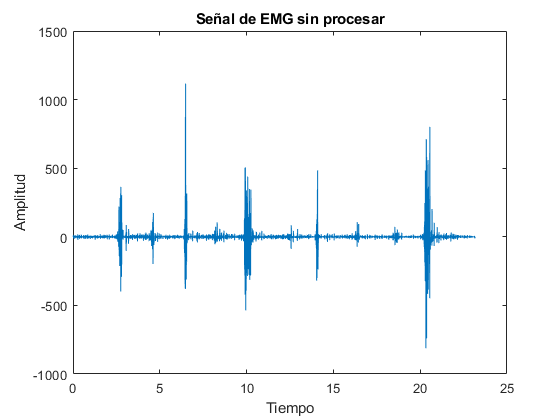







%Cargamos el archivo  y limpiamos el workspace

load('EMG 2 channel Wrist Flex_Ext_Raw.mat')

Fs = 1500;            % Frecuencia de muestreo                    
T = 1/Fs;             % Periodo de muestreo       
L = 34740;             % Longitud de la señal
t = (0:L-1)*T;        % Time vector
X=Data{2};

plot(t,X)
title('Señal de EMG sin procesar')
xlabel('Tiempo')
ylabel('Amplitud')

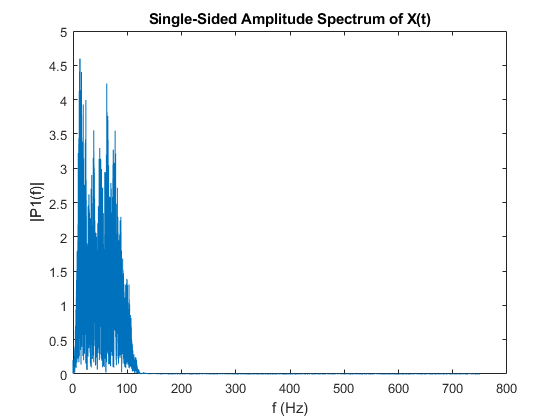



Y = fft(X);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

%Analisis inicial de la señal 



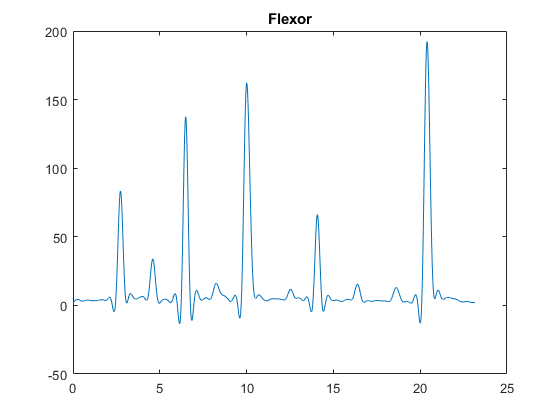

% RAW_DATA_EXTRACTION
%% BACK_SQUAT
%%% VISIT_ONE
clear all;
close all;
clc;

load('EMG 2 channel Wrist Flex_Ext_Raw.mat')%Se carga el archivo de datos sin prepocesado

time = Data{1};
Flex = Data{2};
Exte = Data{3};

%FILTER
% Lowpass filter 500Hz
Freq = 1500;
NyqFreq = Freq/2;
Lowpass = 500;
Wn = Lowpass/NyqFreq;
[B,A] = butter (4,Wn,'low');
% run filter
FlexPBajo = filtfilt(B,A,Data{2});
ExtePBajo = filtfilt(B,A,Data{3});
% Highpass filter 10Hz
Highpass = 10;
Wo = Highpass/NyqFreq;
[D,C] = butter (4,Wo,'high');
% run filter
FlexPAlto = filtfilt(D,C,FlexPBajo);
ExtePAlto = filtfilt(D,C,ExtePBajo);
% Full wave rectification of EMG
FlexRect = abs(FlexPAlto);
ExteRect = abs(ExtePAlto);

% Linear envelope (2Hz lowpass)
LP = 2;
Wp = LP/NyqFreq;
[F,E] = butter (4,Wp,'low');
FlexEnv = filtfilt(F,E,FlexRect);
ExteEnv = filtfilt(F,E,ExteRect);
plot(time, FlexEnv)
title("Flexor")

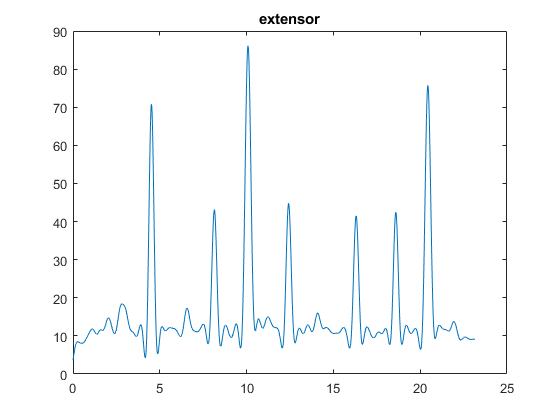

plot(time, ExteEnv)
title("extensor")


% Para realizar la clasificacion de los estados se han seleccionado dos
% umbrales de forma arbitrariaescogidos en base a la forma normalizada de la señal
% a partir de los cuales existe contraccion.
% Por defecto se crea un vector de unos que significa que la señal esta en
% reposo, a continuacion se realiza una  comprobacion punto a punto y se
% modifica el valor de dicho punto si cumple alguna de las dos condiciones 
% planteadas en el bucle

%Algoritmo que en base a unos criterios de umbral 
%Clasifica la señal en tres zonas.
%
% y(extensor)|  contrac.        |      co-contraccion
%            |  extensor        |
%            |     (01)                      (11)
%         20 |_ _ _ _ _ _ _ _ _ | _ _ _ _ _ _ _ _ _ _ _ 
%            |
%            |  relajacion      |      contrac.
%            |      (00)                 flexor
%            |                             (10)
%            |__________________|______________________
%           0                  35              x(flexor)
%
%Co-contraccion --> 3
%Contraccion -->    2
%Relajacion -->     1


[fila,columna]=size(FlexEnv);%Obtenemos las dimensiones de la matriz
umbrales=[35,20];%Establecemos los umbrales de forma externa de modo que sea mas sencillo modificarlos
resultados=zeros(fila,2);

%Columna 1: Datos del flexor discretizados "relajacion""contraccion""cocontraccion"
%Columna 2: Datos del extensor discretizados
%Columna 3: Estado de  la protesis
estados_forzados=[2,4,6]%"flexion","pronacion","cierre"

estados_forzados =      2     4     6


estados_relax=[3,5,7]%"extension","supinacion","apertura"

estados_relax =      3     5     7


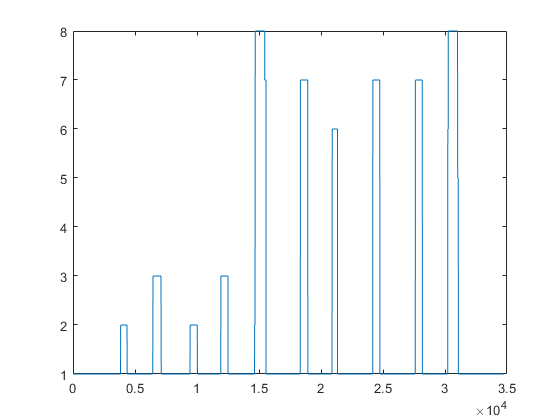

estado=1;
pos=1;
while pos<fila
    

    if (FlexEnv(pos)>=umbrales(1) & ExteEnv(pos)>=umbrales(2))%Co contraccion
        resultados(pos,1)=1;
        resultados(pos,2)=1;
        if estado==1
            estado=2;
        elseif estado==2
            estado=3;
        elseif estado==3
            estado=1;
        end
        %Cambio de estado
        Estados(pos,1)=8;%"Cambio de estado"
        
    elseif (FlexEnv(pos)<umbrales(1) & ExteEnv(pos)>=umbrales(2)) 
        resultados(pos,1)=0;
        resultados(pos,2)=1;
        Estados(pos,1)=estados_relax(estado);
    elseif(FlexEnv(pos)>=umbrales(1) & ExteEnv(pos)<umbrales(2))
        resultados(pos,1)=1;
        resultados(pos,2)=0;
        Estados(pos,1)=estados_forzados(estado);
    else
        resultados(pos,1)=0;
        resultados(pos,2)=0;
        Estados(pos,1)=1;%"Relajacion"
    end
    pos=pos+1;
end


plot(Estados)

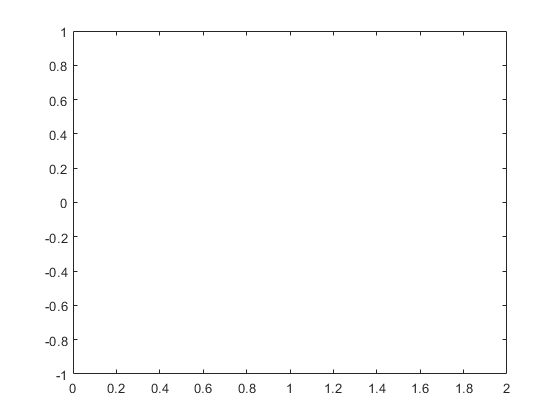


plot(resultados(1))

plot(resultados(2))

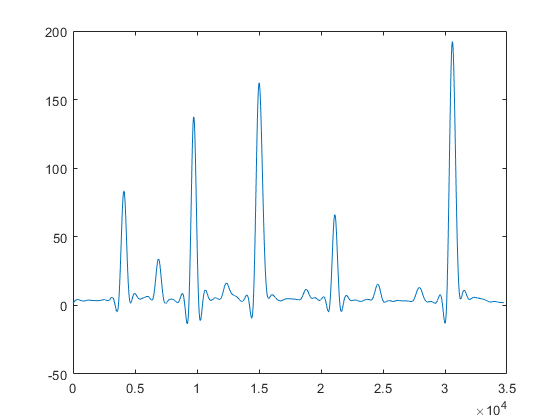

plot(FlexEnv)